% new perspectives 

clear
clear image

% Path for Q2 image
ImagePath = 'https://i.ibb.co/cCt7Rx7/Q2-image.jpg'

% selecting points on gray scale image 
pointsOnImage = [];
[Img, Col]= imread(ImagePath);

gsimage = rgb2gray(Img);

gsimage = 822×592 uint8 matrix
   57   54   51   50   50   50   48   46   42   43   42   40   42   45   43   37   35   35   35   35   35   35   35   35   34   34   34   34   34   34   34   34   37   38   41   42   42   39   34   31   33   33   33   34   35   35   36   36   36   37
   55   52   50   49   49   49   48   47   45   47   46   44   45   48   45   40   35   35   35   35   35   35   35   35   34   34   34   34   34   34   34   34   37   39   41   42   42   38   34   31   33   33   33   34   35   35   36   36   35   38
   54   52   49   48   49   49   49   49   47   49   49   47   46   47   44   40   35   35   35   35   35   35   35   35   34   34   34   34   34   34   34   34   38   39   41   42   42   38   34   30   33   33   34   34   35   35   35   36   33   40
   56   54   51   49   49   49   50   50   47   49   50   48   46   45   42   39   36   35   35   35   34   35   35   35   34   34   34   34   34   34   34   34   38   39   41   42   42   38   33   30   33   34   34 

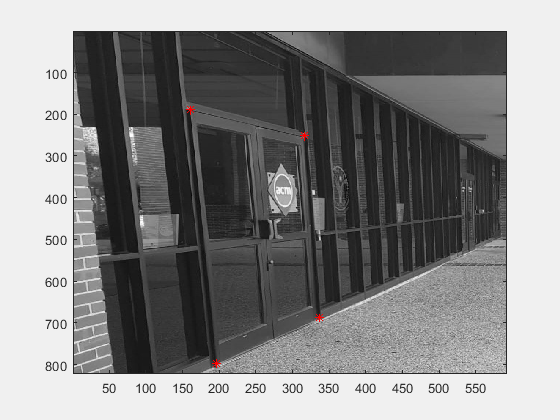

image(gsimage); drawnow; hold on;
colormap(gray(256))
for i=1:4
[x, y]=ginput(1);
v=[x;y];
plot(x, y, 'r*');
pointsOnImage=[pointsOnImage v];
end

disp(pointsOnImage);

  160.7765  316.2788  196.2419  336.7396
  188.6254  250.9344  797.3367  687.0977



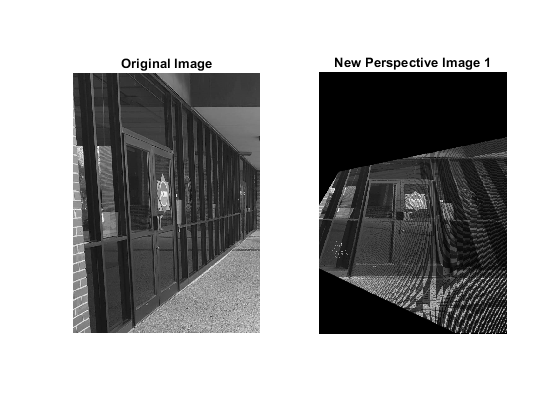

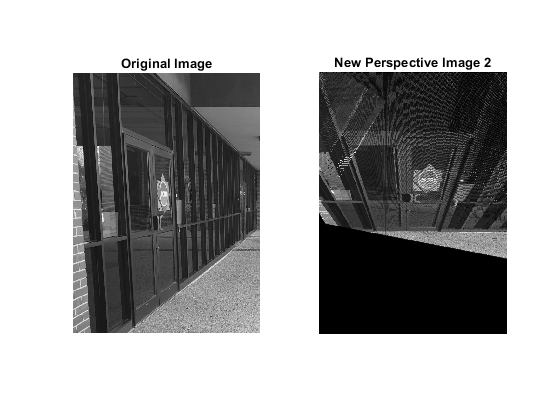

    
[rows,cols,~] = size(gsimage);

% generate 2 new perspective distortion images 
nop = 2;
for n =1:nop
   
    newImage = zeros(rows,cols);
    if(n ==1)
      newImagePoints = [160 360 100 420; 340 340 640 640;1 1 1 1];
    elseif(n ==2)
      newImagePoints = [80 480 180 380; 200 200 500 500;1 1 1 1];
    end

    M = [];
    for j=1:4    
       r1 = [0 0 0  -newImagePoints(1,j) -newImagePoints(2,j) -newImagePoints(3,j) pointsOnImage(2,j)*newImagePoints(1,j) pointsOnImage(2,j)*newImagePoints(2,j) pointsOnImage(2,j)*newImagePoints(3,j)]; 
       r2 = [newImagePoints(1,j) newImagePoints(2,j) newImagePoints(3,j) 0 0 0 -pointsOnImage(1,j)*newImagePoints(1,j) -pointsOnImage(1,j)*newImagePoints(2,j) -pointsOnImage(1,j)*newImagePoints(3,j)];
        
        M = [M; r1; r2];
    end
    
    [U,S,V] = svd(M);
    M1 = V(:,end);
    Homography = reshape(M1,[3,3]);


    for i=1:cols
        for j=1:rows
            point = [i j 1];
            
            pointOnNew = point*inv(Homography);
            
            xUnDist = ceil(abs(pointOnNew(1)/abs(pointOnNew(3))));
            yUnDist = ceil(abs(pointOnNew(2)/abs(pointOnNew(3))));
          
            if(yUnDist >= 1 && yUnDist <=rows && xUnDist >=1 && xUnDist <=cols)      
                
                newImage(yUnDist,xUnDist) = gsimage(j,i);
            end
            
        end
    end

    for i=2:cols-1
        for j = 2:rows-1
            if(newImage(j,i)==0)
                newImage(j,i) = (newImage(j,i-1) + newImage(j,i+1)+ newImage(j+1,i) + newImage(j-1,i))/4;
                %newImage(j,i) = (newImage(j+1,i-1) + newImage(j+1,i+1)+ newImage(j-1,i-1) + newImage(j-1,i+1))/4;
            
            end
        end
    end
    heading = ['New Perspective Image ',num2str(n)];
    figure;
    subplot(1,2,2),imshow(newImage,[],'InitialMagnification','fit'),title(heading);        
    subplot(1,2,1),imshow(gsimage),title('Original Image');

end
